## Ejercicio 8 del Boletín 3

Este problema resuelve la adaptación de la carga (modificarla para que la línea vea una impedancia normalizada $z=1$, utilizando una línea detransmisión de longitud variable *d* en paralelo con un stub (línea de transmisión terminada en cortocircuito) de longitud *s* también variable.

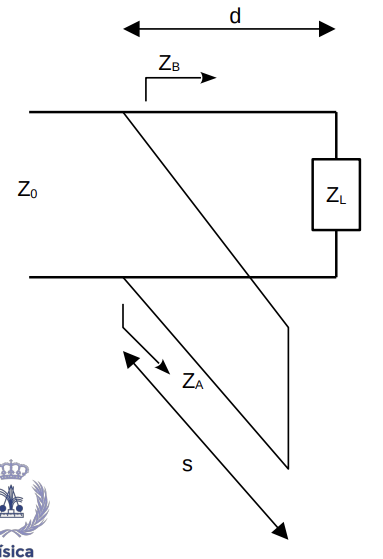

Como siempre, la clave es la ecuación que proviene del circuito. En este caso tenemos la asociación de la impedancia de entrada de la línea con la carga, $z_n$, en paralelo con la impedancia de entrada del stub, $z_A$, que debe ser la carga acoplada $z_{\textrm{in}} =1$.


$$z_{\textrm{in}} =z_n \|z_A =1$$


Manipulamos un poco esta ecuación para que nos dé una forma más sencilla de trabajar:

$1=z_n \|z_A =\frac{1}{\frac{1}{z_n }+\frac{1}{z_A }}$;

$1=\frac{1}{z_n }+\frac{1}{z_A }=y_n +y_A$;

$y_n =1-y_A$;


$$g_n +jb_n =1-jb_A$$


Es decir, que la admitancia de entrada de la línea de transmisión con la carga, deber ser 1 + un valor imaginario puro que se compensa completamente con el stub.

#### Primera parte: Impedancia de acoplo.

Le pedimos a la impedancia de entrada de la línea de transmisión con la carga que valga 1 + un valor imaginario puro. Buscamos la impedancia de carga en la carta:

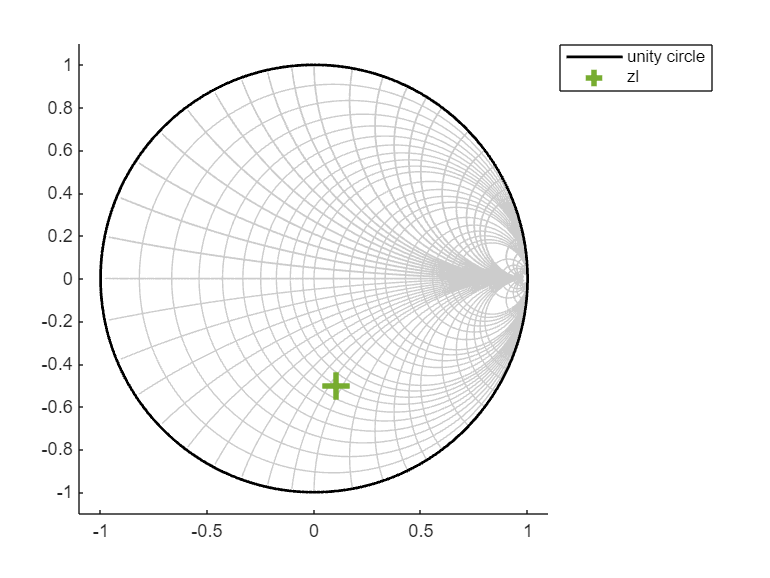

sm = Smithchart;
sm = sm.addz(0.7 - 1j*0.95, "zl");  % EDITABLE. Añadimos la carga a la línea
sm.plotall("lines");

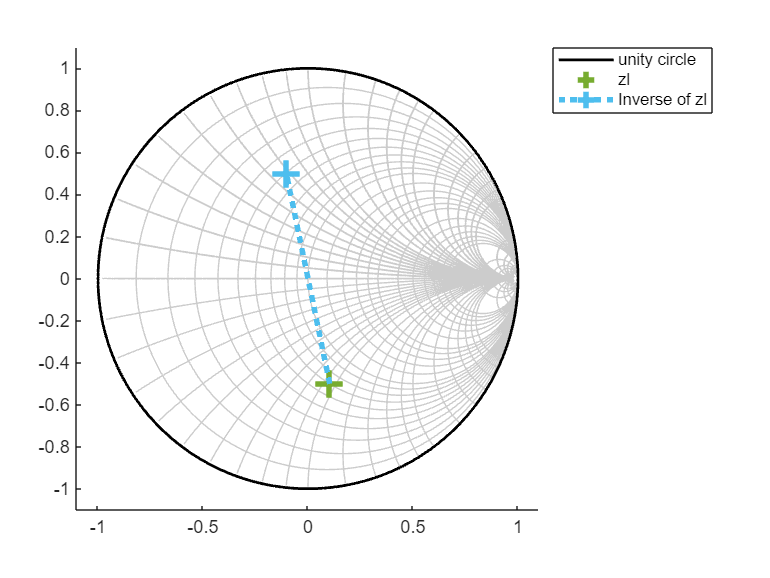

sm = sm.inverseimped();  % Buscamos su admitancia
sm.plotall("lines");

Extendemos la línea, tanto como sea necesario:

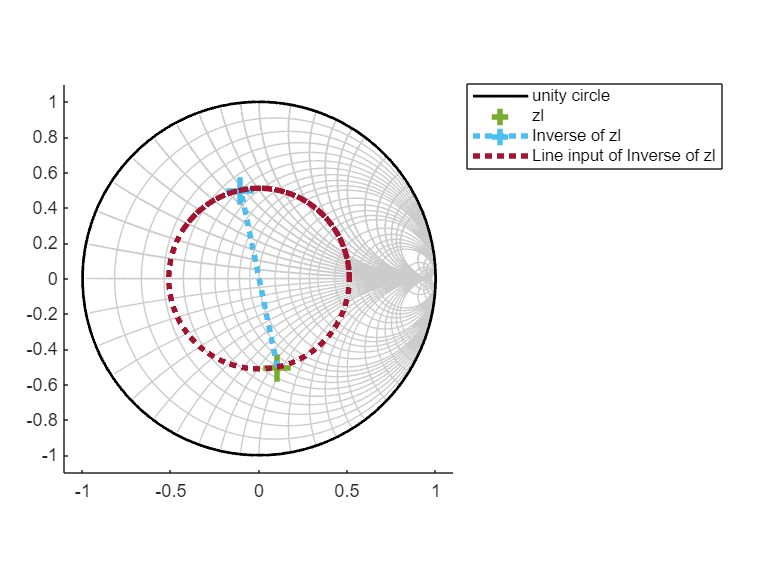

sm = sm.inputimped();  % dibujamos en la carta todas las
                       % posibles admitancias que se obtienen
                       % alargando la línea
sm.plotall("lines");

Buscamos la condición de acoplo, lo que da dos puntos en los que la admitancia de entrada $y_n$ de la linea de transmisión con la carga tiene un valor de 1 más un valor imaginario puro.

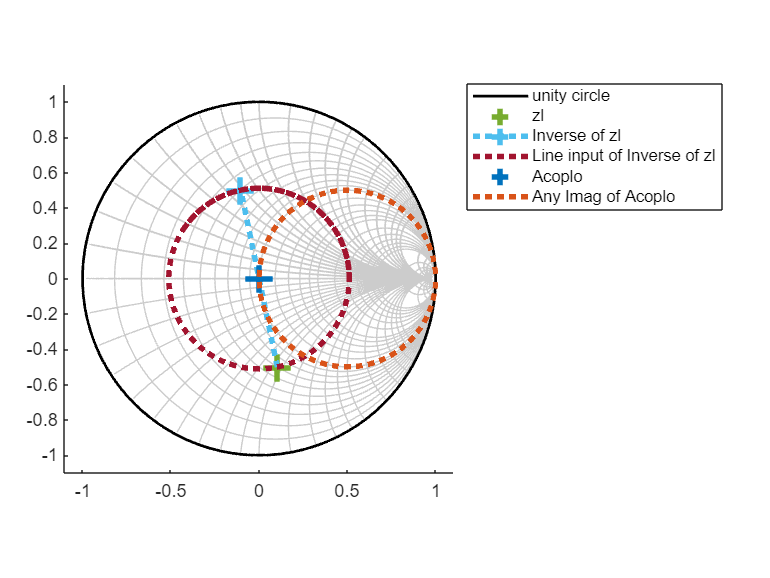

sm = sm.addz(1, "Acoplo");  % Introducimos la condición de acoplo
sm = sm.imagfree();         % Le añadimos cualquier valor imaginario
sm.plotall("lines");

#### Segunda parte: longitud del stub

Eligiendo uno de los dos puntos de corte, vemos que la impedancia de la linea tiene una parte compleja que tenemos que compensar con el stub. Efectivamente, como se muestra en la figura, un stub tiene una impedancia y una admitancia que siempre son imaginarias.

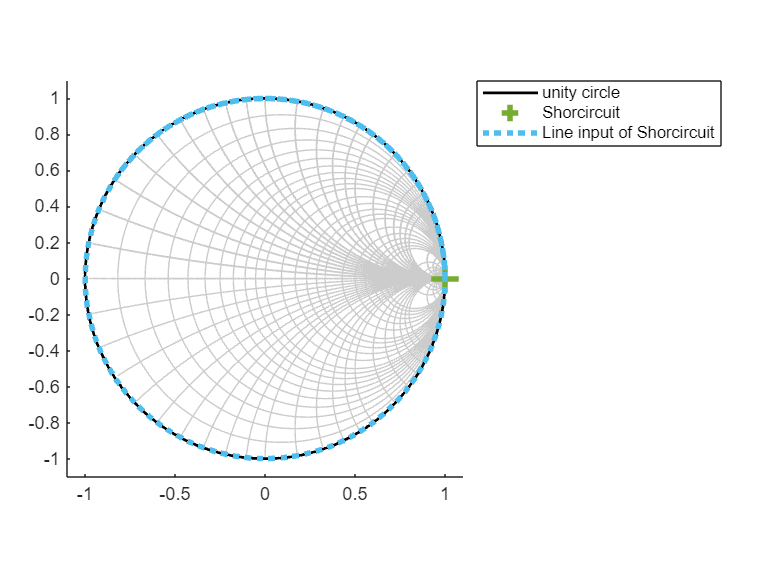

sm = Smithchart;
sm = sm.addz(inf, "Shorcircuit"); % Admitancia del cortocircuito
sm = sm.inputimped();  % Le añadimos cualquier valor imaginario
sm.plotall("lines");

Sólo queda leer las distancias para conocer la longitud de la línea de transmisión con la carga y la longitud del stub.

Observe que cualquier carga se puede adaptar con el método del stub.